% Transformada Z

clear all;
clc;
close all;



$$F(z) =  \frac{z^2+4z}{z^3-3z^2+4z-2}$$


N = 200;

x    = ones(1,N);              % entrada - definida pelo usuário
y(1) = 0;
y(2) = 0;
y(3) = 0;

x(1) = 0;
x(2) = 0;
x(3) = 0;

for k = 4:N

%  indice tem que ser maior do que zero
%  y(4) = 3*y(3)- 4*y(2) +2*y(1) + x(3) + 4*x(2);  

y(k) = 3*y(k-1)- 4*y(k-2) +2*y(k-3) + x(k-1) + 4*x(k-2);  

% Atalizar os valores y(k)

y(k-1) = y(k);
y(k-2) = y(k-1);
y(k-3) = y(k-2);

end

## Visualização

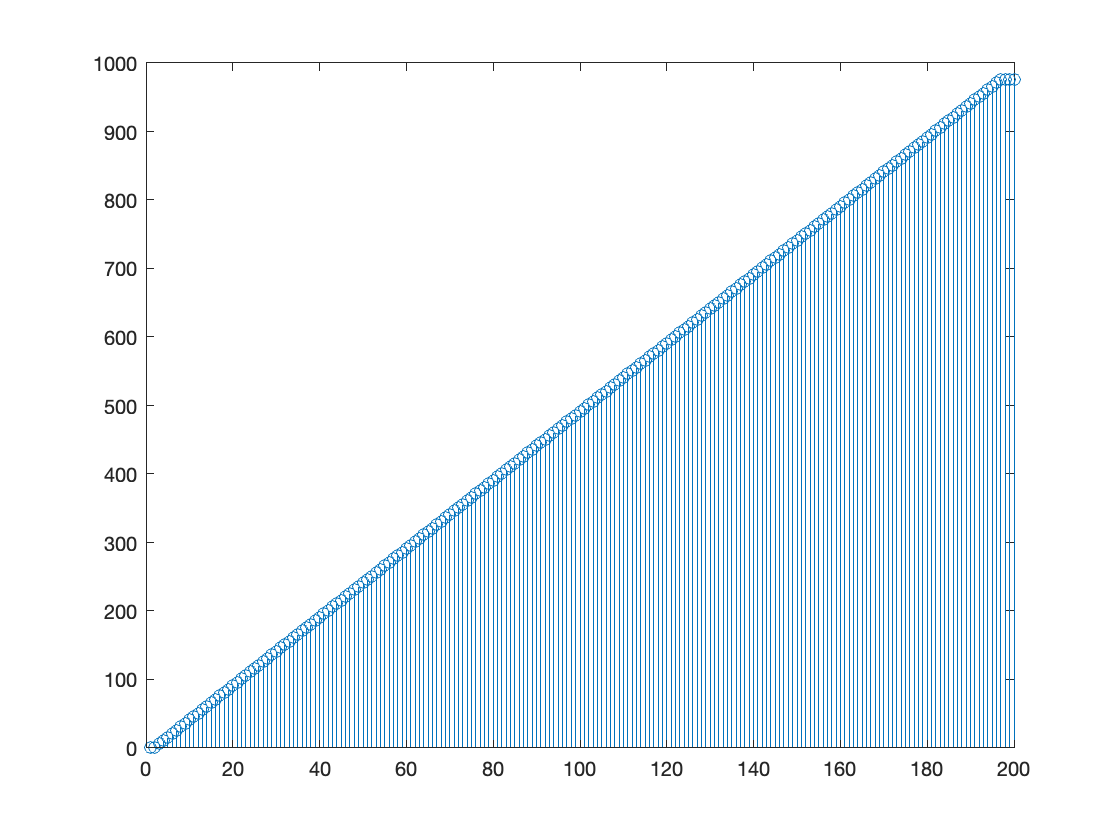

stem(y)